# Time lapsed tSNE plots of syllables

### Choose settings

% Query for syllables to be retrieved
birdname = 'br177yw112';
syls = ['bkcrd'];
days = [62,661,68,73,86,88];

% set spectogram parameters
max_syl_duration = 31; % in milliseconds
overlap_windowsize = [0.9 10]; %pct overlap, bin size (msec)
numWindows = calcNumWindows(max_syl_duration,overlap_windowsize);

segment_duration = 0.0310

bin_duration = 0.0100

overlap = 0.9000

Number of bins: 30


whichWindows = ['1_to_' num2str(numWindows)];%['end-' num2str(numWindows) '_to_end'];
spect_params = struct("overlap_windowsize",overlap_windowsize,"numWindows",numWindows,"whichWindows",whichWindows);

### Compile the spectrogram matrices for syllable trials

% directory where compiled data will be saved
savedir = "C:\Users\LPASCU2\OneDrive - Emory University\MATLAB_CODE\ephys-songbird\data\processed\tSNE_syllable_spects";
[spects_all,labels_all,days_all] = compileSylSpects(birdname,syls,days,savedir,spect_params);

spect_params = struct with fields:
    overlap_windowsize: [0.9000 10]
            numWindows: 30
          whichWindows: '1_to_30'


day = 62

min_win_length = 39

ind_min = 21

syl_min_win = 'c'

day = 661

min_win_length = 45

ind_min = 652

syl_min_win = 'c'

day = 68

min_win_length = 38

ind_min = 467

syl_min_win = 'r'

day = 73

min_win_length = 40

ind_min = 1829

syl_min_win = 'd'

day = 86

min_win_length = 31

ind_min =         1059
        2166


syl_min_win = 'dd'

day = 88

min_win_length = 35

ind_min = 2114

syl_min_win = 'c'

## Compile the matrix for feeding to tsne

% Step 3: Prepare Data for t-SNE 

% Choose whether to use min duration spects or max duraton, zero padded spects
filename = 'spectrograms_br177yw112_syls_bkcrd_days62_66_68_73_86_88_windows_1_to_30.mat'

filename = 'spectrograms_br177yw112_syls_bkcrd_days62_66_68_73_86_88_windows_1_to_30.mat'

load(filename,'spects_all_zero_padded')

featureMatrix = spects_all_zero_padded; % spects_all or spects_all_zero_padded

% Step 4: Apply t-SNE with 3 dimensions
rng(42); % Set random seed for reproducibility
[tsneResult_zeropadded_perp_120_exg_5,loss] = tsne(featureMatrix, 'NumDimensions', 3,'Perplexity',120,'Exaggeration',5);
disp(loss)

    1.3237



save(filename,'tsneResult_zeropadded_perp_120_exg_5','-append')

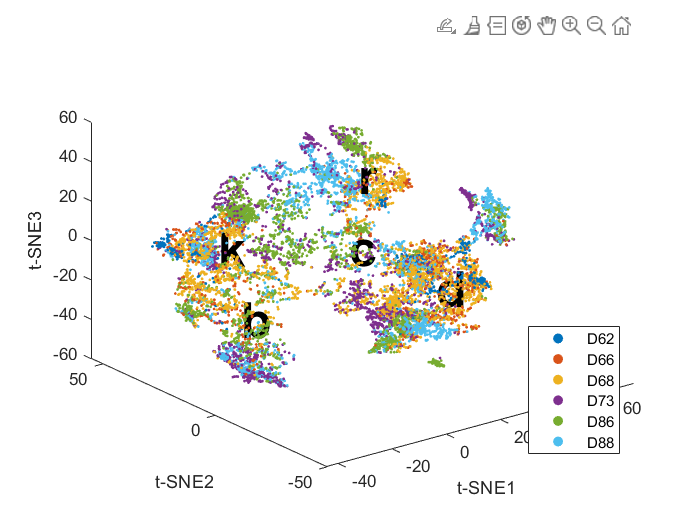

% Step 5: Assign unique colors based labels
plotLabel = days_all; % assign which labels for coloring and grouping

% Step 5b: Optional - assign unique colors based on second label
plotLabel2 = labels_all; % assign which labels for coloring and grouping
  
% Create 3D scatter plot
plot3Dtsne(tsneResult_zeropadded_perp_120_exg_5,plotLabel,plotLabel2)


% Save figure
savefig(gcf,[filename(1:end-4) '_zero_padded_perp_120_exg_5.fig'])

% Load your matrix (replace with your actual file path)
filename = 'spectrograms_syls_bkcrd_days62_66_68_73_86_88_windows_1_to_30.mat';
load(filename)

% Define the tSNE on the whole dataset
tsneResultAll = tsneResult_zeropadded_perp_120_exg_5;

% Fix the xyz axes based on the max values of the tsne results
ax_mins = [min(tsneResultAll(:, 1)), min(tsneResultAll(:, 2)), min(tsneResultAll(:, 3))];
ax_maxes = [max(tsneResultAll(:, 1)), max(tsneResultAll(:, 2)), max(tsneResultAll(:, 3))];

% Define parameters
bin_width = 1000;
bin_step = 50;

% Create a VideoWriter object
video_filename = [filename(1:end-4), '_MOVIE_bw' num2str(bin_width) '_step' num2str(bin_step) '.avi'];
video_writer = VideoWriter(video_filename);
video_writer.FrameRate = 5;
open(video_writer);

% Extract the base name for the directory
[folderPath, baseFileName, ~] = fileparts(video_filename);
newDir = fullfile(folderPath, baseFileName);
mkdir(newDir); % Create the new directory

figure;

for start_row = 1:bin_step:(size(tsneResult, 1) - bin_width + 1)
    end_row = start_row + bin_width - 1;
    
    % Extract the current window and labels
    tsneResult_bin = tsneResultAll(start_row:end_row, :);
    plotLabel = labels_all(start_row:end_row);
    uniqueLabels = unique(plotLabel);
    numUniqueLabels = numel(uniqueLabels);
    colors = lines(numUniqueLabels); % You can use any colormap you prefer
    
    % Create a color map based on labels
    labelColors = zeros(length(plotLabel), 3);
    for i = 1:numUniqueLabels
        labelColors(plotLabel == uniqueLabels(i), :) = repmat(colors(i, :), sum(plotLabel == uniqueLabels(i)), 1);
    end

    % Create 3D scatter plot
    hold on;
    for i = 1:numUniqueLabels
        idx = plotLabel == uniqueLabels(i);
        scatter3(tsneResult_bin(idx, 1), tsneResult_bin(idx, 2), tsneResult_bin(idx, 3), 3, labelColors(idx, :), 'filled');
        
        % Label each cluster with the associated character
        centroid = mean(tsneResult_bin(idx, :), 1);
        text_color = labelColors(find(idx, 1), :);
        text(centroid(1), centroid(2), centroid(3), uniqueLabels(i), 'FontSize', 30, 'FontWeight', 'bold', 'Color', text_color);
    end
    hold off;

    % Set the axes limits
    xlim([ax_mins(1) ax_maxes(1)]);
    ylim([ax_mins(2) ax_maxes(2)]);
    zlim([ax_mins(3) ax_maxes(3)]);

    % Additional formatting
    title(['br177yw112']); % Adjust title as needed
    xlabel('t-SNE1');
    ylabel('t-SNE2');
    zlabel('t-SNE3');
    view(3); % Set the view to 3D

    % Pause for a short duration to create the animation effect
    pause(0.1);

    % Save the figure in .fig format
    % figureFilename = fullfile(newDir, sprintf('Figure_%d.fig', start_row));
    % savefig(gcf, figureFilename);

    % Capture the current frame for the movie
    frame = getframe(gcf);
    writeVideo(video_writer, frame);

    % Clear the current figure for the next iteration
    clf;
end

% Close the video writer
close(video_writer);
